## **นำเข้าข้อมูล เพื่อทำโมเดลจำแนกภาพหมาและแมว**

cat_dog = imageDatastore("test_set/","IncludeSubfolders",true,"LabelSource","foldernames")

cat_dog =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Windows 10 Pro\Documents\MATLAB\test_set\cats\cat.4001.jpg';
                              'C:\Users\Windows 10 Pro\Documents\MATLAB\test_set\cats\cat.4002.jpg';
                              'C:\Users\Windows 10 Pro\Documents\MATLAB\test_set\cats\cat.4003.jpg'
                               ... and 2020 more
                              }
                     Folders: {
                              'C:\Users\Windows 10 Pro\Documents\MATLAB\test_set'
                              }
                      Labels: [cats; cats; cats ... and 2020 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreIma

## **แบ่งข้อมูลแต่ละ Label เพื่อใช้ trian (ฝึกฝนโมเดล) และ validation (วัดประสิทธิภาพโมเดล)**

## **โดยแบ่ง Training Data จำนวน 90% ของข้อมูลทั้งหมด และ Validation Data 10%**

[imtrain,imval] = splitEachLabel(cat_dog,0.9)

imtrain =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Windows 10 Pro\Documents\MATLAB\test_set\cats\cat.4001.jpg';
                              'C:\Users\Windows 10 Pro\Documents\MATLAB\test_set\cats\cat.4002.jpg';
                              'C:\Users\Windows 10 Pro\Documents\MATLAB\test_set\cats\cat.4003.jpg'
                               ... and 1818 more
                              }
                     Folders: {
                              'C:\Users\Windows 10 Pro\Documents\MATLAB\test_set'
                              }
                      Labels: [cats; cats; cats ... and 1818 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreIma

imval =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Windows 10 Pro\Documents\MATLAB\test_set\cats\cat.4900.jpg';
                              'C:\Users\Windows 10 Pro\Documents\MATLAB\test_set\cats\cat.4901.jpg';
                              'C:\Users\Windows 10 Pro\Documents\MATLAB\test_set\cats\cat.4902.jpg'
                               ... and 199 more
                              }
                     Folders: {
                              'C:\Users\Windows 10 Pro\Documents\MATLAB\test_set'
                              }
                      Labels: [cats; cats; cats ... and 199 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


## **ทำ Data Augmentation โดยนำข้อมูลรูปภาพจาก Training Data มาหมุน (RandRotation) และกลับด้านรูปภาพ (RandXReflection)**

auds = augmentedImageDatastore([224 224],imtrain,'DataAugmentation', ...
 imageDataAugmenter("RandRotation",[-180 180],"RandXReflection",true))

auds =   augmentedImageDatastore with properties:

             NumObservations: 1821
                       Files: {1821×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: [1×1 imageDataAugmenter]
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


imageDataAugmenter

ans =   imageDataAugmenter with properties:

           FillValue: 0
     RandXReflection: 0
     RandYReflection: 0
        RandRotation: [0 0]
           RandScale: [1 1]
          RandXScale: [1 1]
          RandYScale: [1 1]
          RandXShear: [0 0]
          RandYShear: [0 0]
    RandXTranslation: [0 0]
    RandYTranslation: [0 0]


## **ดูจำนวนข้อมูล Training Data ของแต่ละ Label หลังผ่านการทำ Data Augmentation แล้ว**

[num,~,ic] = unique(imtrain.Labels);

a_table = table(num,accumarray(ic,1))

a_table = 2×2 table
    num     Var2
    ____    ____

    cats    910 
    dogs    911 


disp(['Minimum number of training images in a label: ' num2str(min(a_table.Var2))])

Minimum number of training images in a label: 910


## **ทำ Data Augmentation โดยนำข้อมูลรูปภาพจาก Validation Data มาหมุน (RandRotation) และกลับด้านรูปภาพ (RandXReflection**)

valset = [readall(augmentedImageDatastore([224 224],imval))
 readall(augmentedImageDatastore([224 224],imval,'DataAugmentation', ...
 imageDataAugmenter("RandRotation",[-180 180])))]

valset = 404×2 table
          input          response
    _________________    ________

    {224×224×3 uint8}      cats  
    {224×224×3 uint8}      cats  
    {224×224×3 uint8}      cats  
    {224×224×3 uint8}      cats  
    {224×224×3 uint8}      cats  
    {224×224×3 uint8}      cats  
    {224×224×3 uint8}      cats  
    {224×224×3 uint8}      cats  
    {224×224×3 uint8}      cats  
    {224×224×3 uint8}      cats  
    {224×224×3 uint8}      cats  
    {224×224×3 uint8}      cats  
    {224×224×3 uint8}      cats  
    {224×224×3 uint8}      cats  
    {224×224×3 uint8}      cats  
    {224×224×3 uint8}      cats  


## ดูจำนวนข้อมูล Validation Data แต่ละ Label หลังผ่านการทำ Data Augmentation แล้ว

%Total number of validate data for each label

[num,~,ic] = unique(valset.response);

a_table = table(num,accumarray(ic,1))

a_table = 2×2 table
    num     Var2
    ____    ____

    cats    202 
    dogs    202 


## สร้างโมเดลจำแนกภาพหมาและแมว โดยใช้โมเดล GoogleNet มาปรับปรุงใหม่

เรียกใช้ GoogleNet

net2 = googlenet

net2 =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


## สกัด GoogleNet ให้เป็น layer

lgraph = layerGraph(net2)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


## ปรับแต่งโมเดล

โดยเปิด network design ไปที่ new แล้วเลือกที่ from workplace จากนั้นแล้วเลือก lgraph ที่ได้เก็บ Layer graph ที่สกัดจาก network GoogleNet แล้วปรับแต่งโมเดลดังนี้

- ปรับแต่งค่า parameter ใน Layer Convolution2dLayer ที่ชื่อ conv1-7x7_s2, conv2-3x3_reduce และ conv2-3x3 ดังนี้

            - weightLearnRteFactor เป็น 0

            - WeightL2Factor เป็น 1

            - BiasL2Factor เป็น 0

            - Parameter อื่นไม่เปลื่ยนแปลง

          2. เปลี่ยน layer ในโมเดล lgraph ที่ชื่อ loss3-classifier ด้วย layer ใหม่ที่เป็น fullyConnectedLayer ชื่อ fc ที่มีคุณสมบัติดังนี้

            - มี output 2 node

            - มีค่า WeightLearningRateFactor ที่ 10

            - มีค่า BiasLearningRateFactor ที่ 10

          3. เปลี่ยน layer ที่ชื่่อ output ด้วย layer ใหม่ที่เป็น clssificationLayer

แล้ว Export model ที่ปรับแต่งแล้ว (lgraph_1) จากนั้น ปิด network design

deepNetworkDesigner

## **กำหนดขนาด Batch เพื่อแบ่งข้อมูลในการ Train/ปรับ weight**

## **และ option ในการ Train  เช่น ขนาด Batch, จำนวน epoch, optimizer, learning rate เริ่มต้น**

miniBatchSize = 183;

options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',5, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    "ValidationFrequency", 50,...
    'ValidationData',valset, ...
    'Verbose',true, ...
    'Plots','training-progress')

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 3.0000e-04
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 5
                   MiniBatchSize: 183
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [404×2 table]
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       

## **เช็ค GPU ที่มีในคอมพิวเตอร์ ถ้ามี GPU ที่ใช้งานได้ ก็จะนำมาใช้งานเพื่อช่วยให้ Train model ได้เร็วขึ้น**

delete(gcp('nocreate'))
if canUseGPU
    executionEnvironment = "gpu";
    numberOfGPUs = gpuDeviceCount("available");
    pool = parpool(numberOfGPUs);
else
    executionEnvironment = "cpu";
    pool = parpool;
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 1).


## **ใช้โมเดล lgraph_1 ที่ผ่านการปรับแต่งแล้วมา train**

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:41 |       43.72% |       59.41% |       1.4211 |       0.7565 |          0.0003 |
|       5 |          45 |       00:06:52 |       87.98% |       95.54% |       0.3190 |       0.1385 |          0.0003 |
|======================================================================================================================|
Training finished: Max epochs completed.


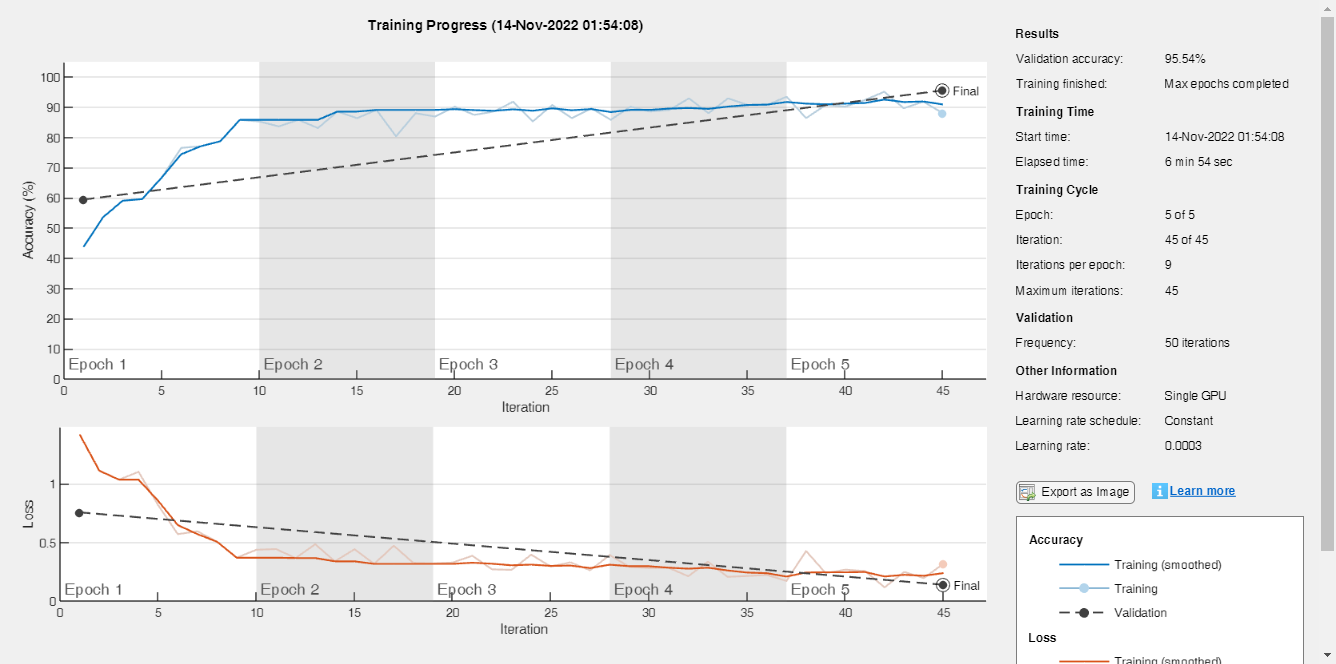

CatDogNet =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'classoutput'}


CatDogNet = trainNetwork(auds,lgraph_1,options)

## **วัดความแม่นยำของโมเดล โดยเอา Validation Data มาให้โมเดลทำนาย และดู score ที่ได้**

[predicted,scores] = classify(CatDogNet,valset);
tableofscores = [table(predicted) array2table(scores,"VariableNames",categories(valset.response))]

tableofscores = 404×3 table
    predicted     cats         dogs   
    _________    _______    __________

      cats       0.99999    1.4254e-05
      cats       0.99618     0.0038216
      cats       0.99569     0.0043086
      cats       0.99996    4.2338e-05
      cats       0.99996    3.7165e-05
      cats       0.88087       0.11913
      cats       0.99997    3.3939e-05
      cats       0.99992    7.5165e-05
      cats             1    3.3699e-06
      cats       0.99909    0.00091159
      cats       0.99956    0.00044321
      cats       0.99996    4.2214e-05
      cats        0.9994    0.00059602
      cats       0.99967    0.00032632
      cats       0.99993    7.4063e-05
      cats        0.9992    0.00080421


## **สร้าง confusion matrix เพื่อดูประสิทธิภาพของโมเดล**

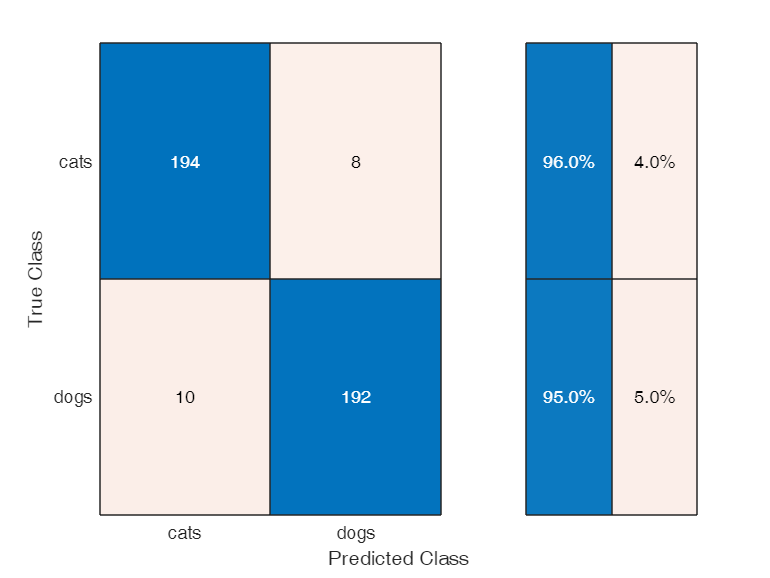

cm2 =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 string]

  Show all properties


cm2 = confusionchart(string(valset.response(1:404)),string(predicted(1:404)),"RowSummary","row-normalized")